%% Model the Rocket's Dynamics
% Rocket parameters
F = 5;    % Thrust force (N)
L = 0.5;       % Moment arm (m)
I = 0.00098;     % Moment of inertia (kg·m²)
K = F*L/I;   % Gain from TVC angle to angular acceleration

% State-space model
A = [0 1; 0 0];
B = [0 0; K 1];  % Inputs: delta (TVC angle), d (disturbance torque)
C = [0 1];       % Output: theta rate (q)
D = [0 0];
rocket = ss(A, B, C, D);
% We change the second input name to 'd_internal' so it can receive the processed disturbance.
rocket.InputName = {'delta', 'd_internal'};
rocket.OutputName = 'q';

%% Define Actuator Model with Uncertainty
% Nominal actuator (first-order lag)
tau = 0.1;
ActNom = tf(1, [tau 1]);

% Uncertainty weighting function
Wunc = makeweight(0.3, [10, 0.2], 0.1);
unc = ultidyn('unc', [1 1]);

% Uncertain actuator model
Act = ActNom * (1 + Wunc * unc);
Act.InputName = 'u';
Act.OutputName = 'delta';

%% Define Performance and Disturbance Weights
% Tracking error weight (emphasize low-frequency performance)
W1 = tf([0.1 1], [1 0.01]);  % High gain at low frequencies
W1.u = 'e';   % e = q_ref - q (q_ref = 0)
W1.y = 'z1';

% Control effort weight (limit high-frequency control action)
W2 = tf(0.01*[1 0.1], [1 100]);
W2.u = 'u';
W2.y = 'z2';

% Disturbance weight (low-frequency torque disturbances)
Wd = tf(0.1, [1 0.01]);  % Weight on disturbance input
Wd.u = 'w1';
Wd.y = 'd';

% Sensor noise weight (high-frequency measurement noise)
Wn = tf(0.01);           % Small noise intensity
Wn.u = 'w2';
Wn.y = 'n';

%% Construct the Generalized Plant
% Define summation blocks with unique names
sum_d = sumblk('d_internal = d');  % Use the output "d" from Wd
sum_n = sumblk('y = q + n');         % Use the output "n" from Wn
sum_e = sumblk('e = -q');            % Tracking error (q_ref = 0)

% Connect all components:
% External inputs: 'w1' (disturbance), 'w2' (sensor noise), 'u' (control command)
% External outputs: 'z1' (from W1), 'z2' (from W2), 'y' (measurement from sum_n)
P = connect(rocket, Act, Wd, Wn, W1, W2, sum_d, sum_n, sum_e, ...
           {'w1', 'w2', 'u'}, {'z1', 'z2', 'y'});

%% Define Controller I/O Dimensions and Synthesize a Controller
nmeas = 1;   % Measurement: y (the output from sum_n)
ncont = 1;   % Control input: u (TVC command)

% Perform μ-synthesis
[Krob, ~, info] = musyn(P, nmeas, ncont);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1               1            1            1             4
    2               1            1            1             4
    3               1            1            1             6

Best achieved robust performance: 1



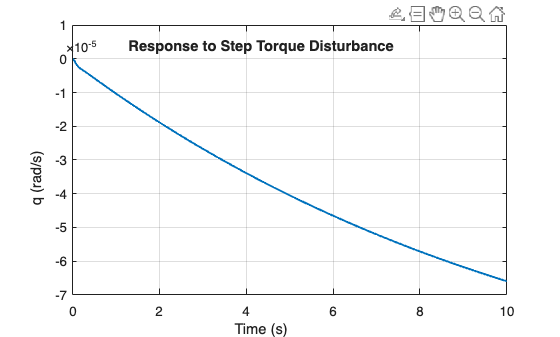


%% Form the Closed-Loop System (Nominal)
CL_nom = lft(P.NominalValue, Krob);

%% Time Response to a Step Disturbance
t = 0:0.01:10;
d_step = 0.1 * ones(size(t));  % Step disturbance signal (torque)
[y, t_out] = lsim(CL_nom('z1', 'w1'), d_step, t);

figure;
plot(t_out, y, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('q (rad/s)');
title('Response to Step Torque Disturbance');
grid on;


%% Robust Analysis
[stabmarg, ~] = robstab(CL_nom);
perfmarg = robgain(CL_nom, 1);  % Target performance level γ = 1

disp('Robust Stability Margin:');

Robust Stability Margin:


disp(stabmarg);

           LowerBound: Inf
           UpperBound: Inf
    CriticalFrequency: NaN



disp('Robust Performance Margin:');

Robust Performance Margin:


disp(perfmarg);

           LowerBound: 0
           UpperBound: 0
    CriticalFrequency: NaN

